% 读取音频数据
%[Data1, fs] = audioread('1.wav');
%[Data2, fs] = audioread('2.wav');

% 读取文件，浮点数按照行存储
Data1 = load('1.mat', '-ascii');
Data2 = load('2.mat', '-ascii');


% 比较指定范围数据
xLength = min(length(Data2), length(Data1)) 

xLength = 31868

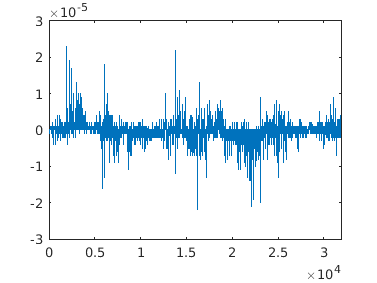

diffData = Data1(1:xLength) - Data2(1:xLength);

% 绘制坐标图
plot(diffData)